clear;clc;close all
% Generate some synthetic data
N = 100; % number of data points
x = rand(N,1); % input variable
y = 2*x + 0.5 + 0.2*randn(N,1); % output variable with Gaussian noise

% Define the likelihood function
likelihood = @(theta) -sum(log(normpdf(y,theta(1)*x+theta(2),0.2))); % negative log-likelihood

% Define the prior distribution
prior = @(theta) log(normpdf(theta(1),0,10)) + log(normpdf(theta(2),0,10)); % log of normal prior

% Define the posterior distribution
posterior = @(theta) likelihood(theta) - prior(theta); % negative log-posterior

% Initialize the parameters
theta0 = [0;0]; % initial guess

% Set the optimization options
options = optimoptions('fminunc','Algorithm','quasi-newton','Display','iter');

% Find the MLE estimate
theta_MLE = fminunc(likelihood,theta0,options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3          3404.74                      3.91e+03
     1           6          234.741    0.000255876            608  
     2           9          118.518              1            165  
     3          15          52.7096             10            451  
     4          18          4.76068              1            240  
     5          21         -13.8566              1       0.000756  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<


% Find the MAP estimate[^1^][1]
theta_MAP = fminunc(posterior,theta0,options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3          3411.18                      3.91e+03
     1           6          241.191    0.000255876            608  
     2           9          124.972              1            165  
     3          15          59.1665             10            451  
     4          18          11.2221              1            240  
     5          21         -7.39219              1       0.000747  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

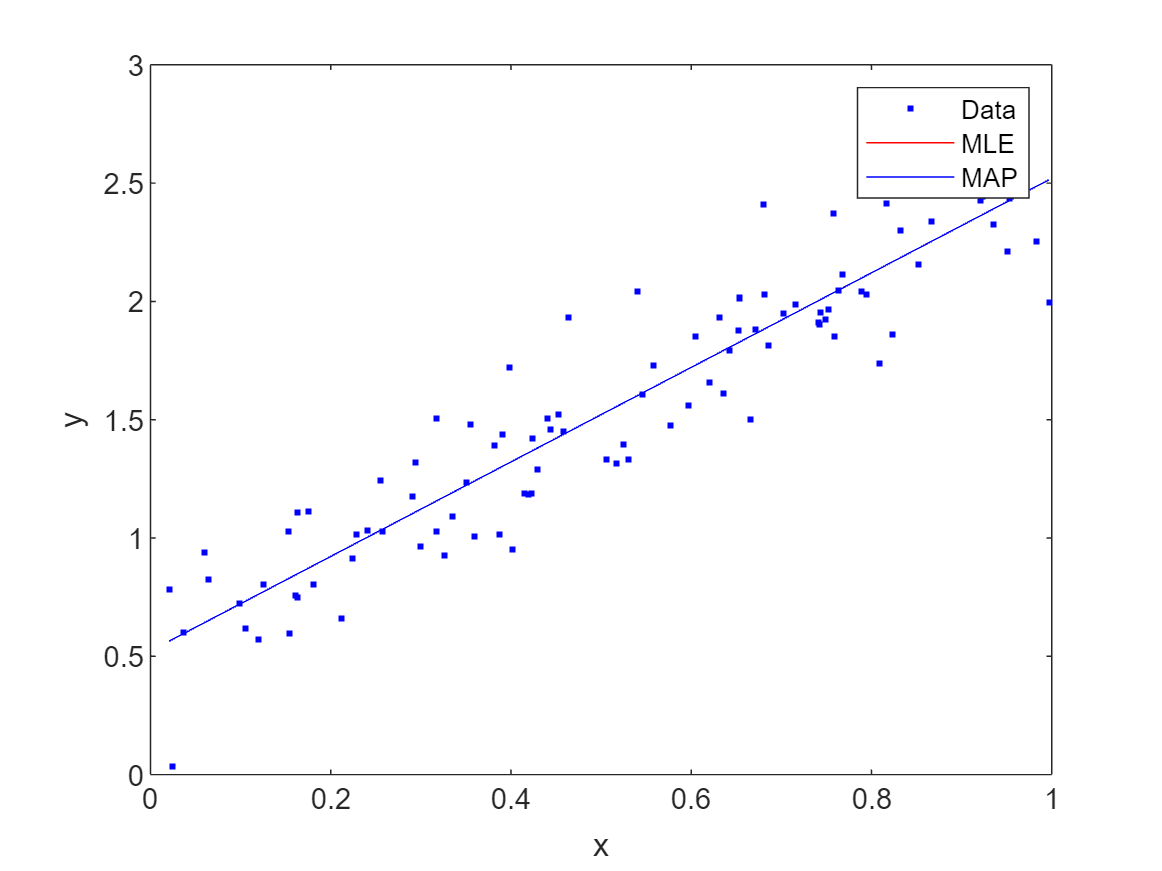


% Plot the data and the fitted lines
figure;
plot(x,y,'b.');
hold on;
plot(x,theta_MLE(1)*x+theta_MLE(2),'r-');
plot(x,theta_MAP(1)*x+theta_MAP(2),'b-');
hold off;
legend('Data','MLE','MAP');
xlabel('x');
ylabel('y');